# **Building a classification model with integrative EEG features**

### **Before running this script...**

- **Install EEGLAB from: **[https://sccn.ucsd.edu/eeglab/download.php](https://sccn.ucsd.edu/eeglab/download.php)

- **Download laplacian_perrinX.m from** [http://mikexcohen.com/lecturelets/laplacian/](http://mikexcohen.com/lecturelets/laplacian/)

## Loading data from '.set' file

## Read the data from the file path

% Get the file list
folderPath = '/Users/yiyuan/OneDrive - University of Essex/PG Research/2_Codes/vBCI_Workshop_Resource/Example_data';
fileDetail = dir(folderPath)

fileDetail = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filename = {};
% Read all file names contained in the data folder
for r = 3:size(fileDetail,1)
    filename{end+1} = fileDetail(r).name;
end
%Get all set files for loading the data
setFileList = filename(contains(filename,'set'));


## Load the data into workspace and segment them

- Epoch length: 10 seconds

- Overlapping ratio between 2 neighbor blocks: 50%

- Reference method: Current source density (Laplacian reference)

- ICA has been applied before loading the dataset

% Create the matrix to store the labels describing the conditions in each
% data bundle (including the numbers of each participant's order and the
% condition (i.e. H,W,S,C,O)
labels = zeros(size(setFileList,2),1);

for order = 1:size(setFileList,2)
    file0 = setFileList{1,order};%Read current filename
    
    labels(order,1) = file0(end-4);%The condition was stored as integers, which can be transformed into chars with the function char()
end

blockDatasetMain = [];
blockLabelMain = [];
ind0 = 0;
overlapLengthB = 0.5; % The ratio of overlapping parts between neighbor blocks
for order = 1:2
    dataSet0 = pop_loadset(setFileList{1,order},folderPath);
    sr0 = dataSet0.srate;%The sampling rate
    % Use CSD (i.e. Laplacian reference) to remove the volumn conduction
    data0 = laplacian_perrinX(dataSet0.data,extractfield(dataSet0.chanlocs,'X'),extractfield(dataSet0.chanlocs,'Y'),extractfield(dataSet0.chanlocs,'Z'));% The tested data
    
    [segData0,times0] = EEGsegment(data0,sr0,1,overlapLengthB);
    numBlocks = size(segData0,3);
    
    blockDatasetMain(:,:,ind0+1:ind0+numBlocks) = segData0;
    blockLabelMain(ind0+1:ind0+numBlocks,:) = ones(numBlocks,1).*labels(order,:);
    ind0 = ind0+numBlocks;
end

pop_loadset(): loading file /Users/yiyuan/OneDrive - University of Essex/PG Research/2_Codes/vBCI_Workshop_Resource/Example_data/H.set ...
Reading float file '/Users/yiyuan/OneDrive - University of Essex/PG Research/2_Codes/vBCI_Workshop_Resource/Example_data/H.fdt'...
pop_loadset(): loading file /Users/yiyuan/OneDrive - University of Essex/PG Research/2_Codes/vBCI_Workshop_Resource/Example_data/W.set ...
Reading float file '/Users/yiyuan/OneDrive - University of Essex/PG Research/2_Codes/vBCI_Workshop_Resource/Example_data/W.fdt'...


save('Dataset_test.mat','blockDatasetMain','blockLabelMain')


## Data pre-processing

### Removing line noise and DC signals

% Remove DC components
alphaTrainset = permute(EEGfilter(permute(blockDatasetMain,[2 1 3]),0.1,'HP',5,'all',500),[2 1 3]);
% Remove line noise (Though it does not matter in this study)
alphaTrainset = permute(EEGfilter(permute(alphaTrainset,[2 1 3]),[45.5 50.5],'BS',5,'all',500),[2 1 3]);

### Filtering

% Filter the signal into alpha band
alphaTrainset = permute(EEGfilter(permute(alphaTrainset,[2 1 3]),[8 12],'BP',5,'all',500),[2 1 3]);

### Hilbert transform

hilbertSeries = hilbert(permute(alphaTrainset,[2 1 3]));
phaseAlpha = permute(angle(hilbertSeries), [2 1 3]);
powerAlpha = permute(abs(hilbertSeries), [2 1 3]);

## Extarcting integrative features

### Phase-based features

alphaISPC = zeros(sum(1:61),size(alphaTrainset,3));% The array to store the ISPCs
k = 1;
for m = 1:62
    phase1 = phaseAlpha(m,:,:);
    for n = m+1:62
        phase2 = phaseAlpha(n,:,:);
        dphase = phase1-phase2;
        alphaISPC(k,:) = abs(mean(exp(1i.*dphase),2));
        k = k+1;
    end
end
alphaISPC = alphaISPC';

### Power-based features

alphaCOH = zeros(sum(1:61),size(alphaTrainset,3));% The array to store the ISPCs
k = 1;
for m = 1:62
    power1 = powerAlpha(m,:,:);
    phase1 = phaseAlpha(m,:,:);
    for n = m+1:62
        power2 = powerAlpha(n,:,:);
        phase2 = phaseAlpha(n,:,:);
        dphase = phase1-phase2;
        alphaCOH(k,:) = (abs(mean(abs(power1).*abs(power2).*exp(1i.*dphase),2)));
        k = k+1;
    end
end
alphaCOH = alphaCOH';

### Different shapes of features (Optional)

% alphaISPCMat = zeros(size(alphaTrainset,1), size(alphaTrainset,1), size(alphaTrainset,3));% The matrix to store the ISPCs
% 
% for m = 1:62
%     phase1 = phaseAlpha(m,:,:);
%     for n = m+1:62
%         phase2 = phaseAlpha(n,:,:);
%         dphase = phase1-phase2;
%         alphaISPCMat(m,n,:) = abs(mean(exp(1i.*dphase),2));
%         alphaISPCMat(m,n,:) = alphaISPC(k,m,n);
%         
%     end
% end


### Crop the dataset into feature selection set and model training set (Basis)

% Crop the indices into a selection set and a model set
selectIndex = randperm(size(alphaISPC,1), floor(size(alphaISPC,1) * 0.3));
modelIndex = find(~ismember(1:size(alphaISPC,1), selectIndex));
% Get corresponding datasets according to their indices
selectGroup = alphaISPC(selectIndex,:);
selectLabel = blockLabelMain(selectIndex,:);
modelGroup = alphaISPC(modelIndex,:);
modelLabel = blockLabelMain(modelIndex,:);

## Feature Selection

The feature selection is based on neighborhood component analysis (ref), which will produce the weights of all features in classification, so we can select the ones with the highest classification weights in model training and testing.

### Select the features with built-in function with cross-validation

% Get the groups for cross-validation
fold = 10;
featureNumber = 10;
crossIndex = crossvalind('Kfold', selectLabel, fold);
% Matrices for storing the information of the selected features
sFeatures = [];
fWeights = [];
for r = 1:10
    selectGroupIndex = (crossIndex == r); % Get the group for selection
    nca = fscnca(selectGroup(selectGroupIndex,:), selectLabel(selectGroupIndex));
    % Get the features with the specific number of the highest weights
    selidxvalue = maxk(nca.FeatureWeights, featureNumber);
    selIndex = zeros(featureNumber,1); %Initializa an array to store the index of the selected features
    
    for w = 1:length(selIndex)
        selIndex(w,1) = find(nca.FeatureWeights == selidxvalue(w));
    end
    % Store all the previous selected feature indices in a matrix
    sFeatures(:,end+1) = selIndex;
    fWeights(:,end+1) = nca.FeatureWeights(selectIndex);
    
end

### Get the selected features

#### Get the selected features

% Get the matrix representing the significant features
load('electrodes.mat');
selectFeatureMat = zeros(62);
conditionFeature = cell(4,1);% Condition labels
conditionFeatureMat = zeros(62,62,4);

#### Project the channel labels into channel pairs' indices

channelPairs = {};
thre = [0 featureNumber];

indices = zeros(62);
k = 1;
for m = 1:62
    for n = m+1:62
        channelPairs{1,end+1} = electrodes(m);
        channelPairs{2,end} = electrodes(n);
        indices(m,n) = k;
        k = k+1;
    end
end
% Read the selected features labels from all conditions
classifierLabelMat = zeros(62,62); % The matrix storing the selected features in all classifiers
classifierClassLabelMat = zeros(62,62,2,2);

weightMatA = zeros(62);
numberMatA = zeros(62);

% Intialize the matrices to store the values

weightMat = zeros(62);
for l = 1:length(sFeatures)
    [a,b] = find(indices == sFeatures(l));
    weightMat(a,b) = weightMat(a,b) + fWeights(l); %Because the number of existences of one channel pair as a selected feature also decided the weight in classification, here the numerical sum is used to represent the cumulative weights
    
end
weightMatA = weightMatA + weightMat;

weightMatA0 = weightMatA/max(weightMatA(:));% Normalize the distribution of the weights in the range between 0 and 1
weightMatABin = zeros(62);

% Get the most significant ones in the specific range
selidxvalueMax = maxk(weightMatA0(:),thre(2));
selidxvalueExe = maxk(weightMatA0(:),thre(1));

selidxvalue = selidxvalueMax(~ismember(selidxvalueMax,selidxvalueExe));

weightMatABin = ismember(weightMatA0,selidxvalue);
weightMatAS = weightMatA0;
weightMatAS(~ismember(weightMatA0,selidxvalue)) = 0;

% Add the binary matrix representing the selected features in the main
% binary matrix
selectFeatureMat = selectFeatureMat + weightMatAS;

#### Plot EEG map

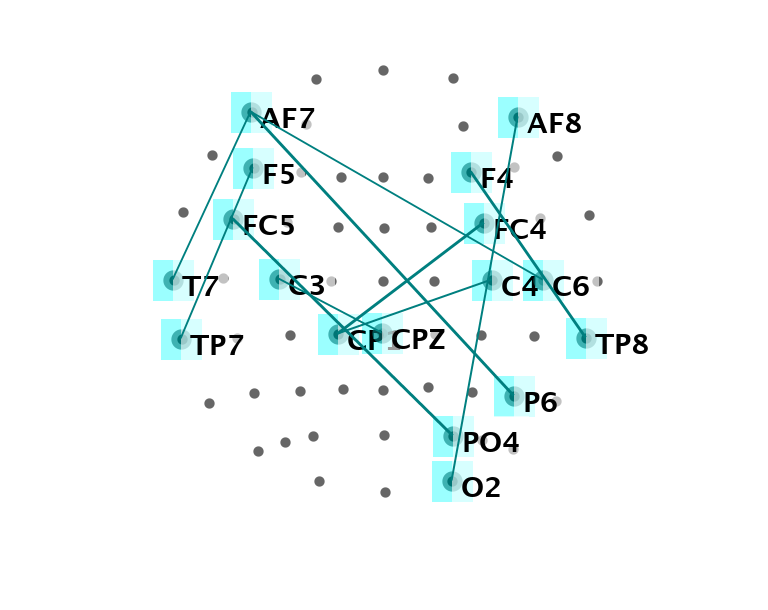

connMap = imread('Empty.tiff');
load('channelPositions.mat')

% Create all reference nodes
for node = 1:size(channelPos,2)
    connMap = insertShape(connMap,'FilledCircle',[channelPos(1,node) channelPos(2,node) 5],'Color',[0 0 0]);
end

[x,y]= find(selectFeatureMat~=0);% Locate the pairs with strong connections
channelPos = floor(channelPos);%Transform coordinates to int
nodes = unique([x;y]);% Get all channels' indices existing in the pairs as the selected classification features

% Highlight the nodes with strong connectivity
for k = 1:length(nodes)
     a = channelPos(1,nodes(k));
     b = channelPos(2,nodes(k));
    
     connMap(b-20:b+20,a-20:a+20) = connMap(b-20:b+20,a-20:a+20) - 100;
     connMap = insertShape(connMap,'FilledCircle',[a,b,10],'Color',[0 127 127]);
     connMap = insertText(connMap,[a b-20],electrodes{nodes(k)},'TextColor',[0 0 0],'BoxColor','white','FontSize',28,'Font','LucidaSansDemiBold');
    
end

for r = 1:size(x,1)
    p1 = channelPos(:,x(r));
    p2 = channelPos(:,y(r));

    connMap = insertShape(connMap,'Line',[p1' p2'],'LineWidth',3,'Color',[0 127 127]);
    
end


connMap = connMap(60:size(connMap,1)-60,60:size(connMap,2)-60,:);
imshow(uint8(connMap))

#### Get the indices of the selected features in the linear shape

selectFeatureIndex = zeros(featureNumber, 1);
[aM,bM] = find(weightMatABin == 1);
for s = 1:featureNumber
    selectFeatureIndex(s) = indices(aM(s),bM(s));
end

## Classification

%% Build the SVM classifier
SVMmodel = fitcecoc(modelGroup(:,selectFeatureIndex), modelLabel);
CVSVMmodel = crossval(SVMmodel, 'kfold', 20); % Cross-validation
CVSMmodel.ScoreTransform = 'symmetricismax';
% Predict
[label,NegLoss,score] = kfoldPredict(CVSVMmodel);
% Get the performance information
cp = classperf(modelLabel, label);


% Output the performance - only from my experience, you can save anything
% you want according to the information stored in cp
perfMat = {};% Matrix to record the performance of the classifiers
participant = 1; % No. of the current participant
classNum = 2; % The number of classified classes

 % Plot the scores
 classLabelOrder = char(CVSVMmodel.ClassNames);
 codingMat = CVSVMmodel.CodingMatrix;
% Write the performance measurement into the performance matrix
row = size(perfMat,1);
perfMat{row+1,1} = participant;
perfMat{row+1,2} = cp.correctRate;
classlabel = cp.ClassLabels;

for m = 1:classNum
    if size(classlabel,1)>=m
        perfMat{row+1,m+2} = char(classLabelOrder(m));
    else
        perfMat{row+1,m+2} = 'U';
    end
end
confMat = cp.CountingMatrix;
confMat = confMat(1:classNum,1:classNum);
if size(classLabelOrder,1)<classNum
    confMat(size(confMat,1)+1:2,:)=0;
    confMat(:,size(confMat,2)+1:2)=0;
end
confMat = confMat';
confMat = confMat(:);
for m = 1:classNum
    for n = 1:classNum
        perfMat{row+1,m*classNum+n+2} = confMat(classNum*(m-1)+n)/sum(confMat(classNum*(m-1)+1:classNum*m));
    end
end

% The result stored in the performance matric, which can be saved in
% different formats
perfMat

perfMat = 1×8 cell array
    {[1]}    {[0.5495]}    {'H'}    {'W'}    {[0.5506]}    {[0.4494]}    {[0.4545]}    {[0.5455]}



% Save the matrix into a csv file
writecell(perfMat, 'perfMat.csv')